clear all
close all
A = [ 4 14 -12;
    0 -4 0;
    1.5 -1 -5];
B = [4; 0; 2];
J = [-1 1.2 3.4;
    -0.25 0.9 0.5;
    -0.85 0.8 2.4];
M = [0; 1; 1];
C = [0 1 0];

maxval = 1e3; %boudning of cvar and dvar

%LMI variables
Pvar = sdpvar(3,3); %Lyapunov matrix
Zvar = sdpvar(3,3); %defining new indepenten matrices
Qvar = sdpvar(3,3);

ii = 100;           % maximal number of iteration steps
jj = 20;            %max rough bisection steps

high = 40;
low = 1e-3;
Flow_stable = false

Flow_stable = logical
   0


%setting bounds based on expected stability of the solution

    if Flow_stable
        % Loop parameters dvar
        lb_dvar = -high;             % initial value lower search bound
        ub_dvar= -low;            % initial value upper search bound
    else
        % Loop parameters dvar
        lb_dvar = low;             % initial value lower search bound
        ub_dvar= high;            % initial value upper search bound
    end
%
d_cvar = 1e-8;      % maximal difference in cvar between to different iteration steps
d_dvar = 1e-8;      % maximal difference in dvar between to different iteration steps

% Set initial loop values

lbf_dvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
    ubf_dvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes
%tracking variables
cvar_track = [];
dvar_track = [];

dwelltime = [];

for i = 1:ii
    %Computing cvar and dvar using bisection
   
    dvar = bisection(lb_dvar,ub_dvar,lbf_dvar,ubf_dvar);
    % Set initial loop values dvar
    lbf_cvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
    ubf_cvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

    %Resetting bounds dvar
    if Flow_stable %we have a minimal dwell time d < 0, c > 0
        % Loop parameters cvar
        lb_cvar = low;             % initial value lower search bound
        ub_cvar = high;            % initial value upper search bound
        
    else %we have a maximal dwell time d > 0, c < 0
        lb_cvar = -high;             % initial value lower search bound
        ub_cvar = -low;            % initial value upper search bound
    end

    for j=1:jj
        %doing a rough bisection of d to find optimal value
         cvar = bisection(lb_cvar,ub_cvar,lbf_cvar,ubf_cvar);
    
        [Pvar,Qvar,Zvar, L,diagnostics] = LMI_q2f(A,J,cvar,dvar,Pvar,Qvar,Zvar);
        
        % Check result
        % pres : Primal constraint residuals
        % dres : Dual constraint residuals
        [pres,~] = check(L);
        [ub_cvar, lb_cvar, lbf_cvar, ubf_cvar] = CheckFeasibility(cvar,ub_cvar, lb_cvar, lbf_cvar, ubf_cvar,pres,diagnostics);
        
        cvar_track(i,j) = cvar; %tracking dvar
        if j > 1
            if abs(cvar-cvar_track(i,j-1)) < d_dvar
                break;              % break loop if accurate enough
            end
        end
    end
    


    %determining feasiblity upper or lower bound
    dwelltime(i) = abs(dvar/cvar); %computing new dwell time
    [ub_dvar, lb_dvar, lbf_dvar, ubf_dvar, feasibleCvar] = CheckFeasibilityCvar(dvar,ub_dvar,lb_dvar,lbf_dvar,ubf_dvar,dwelltime);
   
    
    %storing iteration
    dvar_track(i) = dvar;
    if abs(cvar) > maxval
        display('maximal value cvar reached, unbounded problem')
        break
    elseif abs(dvar) > maxval
        display('maximal value cvar reached, unbounded problem')
        break
    end

    if i>1
        if abs(dwelltime-dwelltime(i-1)) < 1e-1
            break;
        end
    end

    % Store feasible solution
    if feasibleCvar
        feasible.Pvar = Pvar;
        feasible.Qvar = Qvar;
        feasible.Zvar = Zvar;
        feasible.cvar = cvar;
        feasible.dvar = dvar;
    end

end


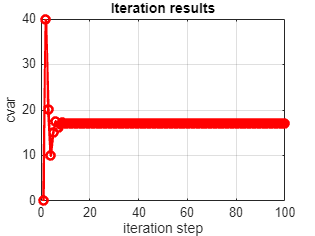


% Plot iteration history
figure(1)
clf
plot(dvar_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('cvar')
title('Iteration results')
grid on



figure()
N = length(cvar_track) %final number of itterations

N = 100

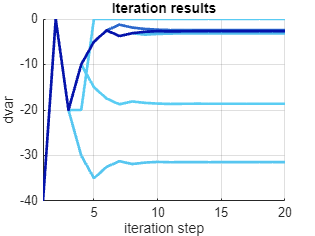

lightBLUE = [0.356862745098039,0.811764705882353,0.956862745098039];
darkBLUE = [0.0196078431372549,0.0745098039215686,0.670588235294118];
 
blueGRADIENTflexible = @(i,N) lightBLUE + (darkBLUE-lightBLUE)*((i-1)/(N-1));

hold on 
for i = 1 :N
    plot(cvar_track(i,:),'color',blueGRADIENTflexible(i,N),'LineWidth',2)
end
xlabel('iteration step')
ylabel('dvar')
title('Iteration results')
grid on
axis tight

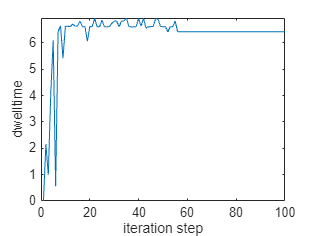


figure()
plot(dwelltime)
xlabel('iteration step')
ylabel('dwelltime')
ylim([0,max(dwelltime(3:length(dwelltime)))])


% Retrieve output
P = value(feasible.Pvar)

P =     2.6003    5.7927   -5.2078
    5.7927   45.2925  -13.7748
   -5.2078  -13.7748   10.8737


c = value(feasible.cvar)

c = -2.4980

d = value(feasible.dvar)

d = 17.0589



dwellTau = abs(d)/abs(c)

dwellTau = 6.8289

syms a b c x1 x2 x3
L = [a; b ;c]

$$L = \left(\begin{array}{c} a\\ b\\ c \end{array}\right)$$

C = [0 1 0]

C =      0     1     0


J - L*C

$$ans = \left(\begin{array}{ccc} -1 & \frac{6}{5}-a & \frac{17}{5}\\ -\frac{1}{4} & \frac{9}{10}-b & \frac{1}{2}\\ -\frac{17}{20} & \frac{4}{5}-c & \frac{12}{5} \end{array}\right)$$

eig(J - L*C)

$$ans = \left(\begin{array}{c} \frac{7}{10}\\ \frac{4}{5}-5\,\sqrt{\frac{b^{2}}{100}-\frac{b}{250}+\frac{a}{100}-\frac{c}{50}+\frac{11}{2500}}-\frac{b}{2}\\ 5\,\sqrt{\frac{b^{2}}{100}-\frac{b}{250}+\frac{a}{100}-\frac{c}{50}+\frac{11}{2500}}-\frac{b}{2}+\frac{4}{5} \end{array}\right)$$